format long eng;
kbr1b_x = importdata("KBR1B_2020-09-17_Y_04.txt");
gni1b_a = importdata("GNI1B_2020-09-17_C_04.txt");
gni1b_b = importdata("GNI1B_2020-09-17_D_04.txt");
sca1b_a = importdata("SCA1B_2020-09-17_C_04.txt");
sca1b_b = importdata("SCA1B_2020-09-17_D_04.txt");

los = gni1b_b.data(:, 1: 3) - gni1b_a.data(:, 1: 3);
dis = sqrt(sum(los.^2, 2));
los = los ./ dis;
rotm_a = zeros(17280, 3, 3);
rotm_b = zeros(17280, 3, 3);
eqa = zeros(17280, 6);
eqb = kbr1b_x(:, 2) - dis(1: 5: end);
for i = 1: 17280
    eqa(i, 1: 3) = los(i*5-4, :) * quat2rotm(sca1b_a.data(i*5-4, 2: 5));
    eqa(i, 4: 6) = los(i*5-4, :) * quat2rotm(sca1b_b.data(i*5-4, 2: 5));
end
diff_eqa = diff(eqa, 1);
% 10522: 11121
% 10822: 11421
% 10822: 11421
% 8636: 9235

% 8636: 9235

diff2_eqa = diff(diff_eqa, 1);
diff3_eqa = diff(diff2_eqa, 1);
diff_eqb = diff(kbr1b_x(:, 2) - dis(1: 5: end));
diff2_eqb = diff(kbr1b_x(:, 2) - dis(1: 5: end), 2);
diff3_eqb = diff(diff2_eqb);
diff2_eqb = filter_pdfree(Num, diff2_eqb);
diff2_eqa = filter_pdfree(Num, diff2_eqa);
diff3_eqa = filter_pdfree(Num, diff3_eqa);
diff3_eqb = filter_pdfree(Num, diff3_eqb);
% fft_diff3_eqb = fft(diff3_eqb(10522: 11021));
% fft_diff3_eqa = [fft(diff3_eqa(10522: 11021, 4)), fft(diff3_eqa(10522: 11021, 5))];
% eqb = [fft_diff3_eqb(11); fft_diff3_eqb(21)];
% eqa = [fft_diff3_eqa(11, :); fft_diff3_eqa(21, :)];
% eqa_real = real(eqa);
% eqa_imag = imag(eqa);
% eqb_real = real(eqb);
% eqb_imag = imag(eqb);
% 
% eqa_abs = abs(eqa);
% eqa_ang = angle(eqa);
% eqb_abs = abs(eqb);
% eqb_ang = angle(eqb);

lsqr(diff3_eqa(8636: 9235, :), diff3_eqb(8636: 9235))

lsqr 在解的 迭代 6 处收敛，并且相对残差为 0.036。


ans =    -1.39657685087057e+000
    2.43743414223536e-003
    3.71602795827923e-003
   -25.9144397770465e-006
    29.2956578519935e-003
    18.1324769188950e-003


lsqr(diff2_eqa(8636: 9235, :), diff2_eqb(8636: 9235))

lsqr 在解的 迭代 6 处收敛，并且相对残差为 0.061。


ans =    -1.39572721404133e+000
    2.51746973616260e-003
    13.6017368896290e-003
   -23.3832420236535e-006
   -24.2069723592602e-003
    54.5277855408344e-003


lsqr(diff3_eqa(10822: 11421, :), diff3_eqb(10822: 11421))

lsqr 在解的 迭代 6 处收敛，并且相对残差为 0.039。


ans =    -1.40493736187664e+000
   -1.11122166463766e-003
   -307.496541687452e-006
    21.3058867156970e-006
   -17.5516522011833e-003
   -32.5528929704544e-003


lsqr(diff2_eqa(10822: 11421, :), diff2_eqb(10822: 11421))

lsqr 在解的 迭代 6 处收敛，并且相对残差为 0.036。


ans =    -1.40488308948607e+000
   -1.09271118956260e-003
    5.35999996790402e-003
   -13.1043211634144e-006
    14.7775148216495e-003
   -27.1384107582049e-003


solver_spectral(diff2_eqa(10822: 11421, :), diff2_eqb(10822: 11421), [1 2], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.21。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.21。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.21。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.22。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.22。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.22。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.21。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.21。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.21。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 1.3e-09。


ans =     1.40694282999796e+000
   -1.07771353133108e-003


solver_spectral(diff3_eqa(10822: 11421, :), diff3_eqb(10822: 11421), [1 2], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.31。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.31。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.31。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.4。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.4。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.4。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.32。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.32。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.32。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 8.9e-12。


ans =     1.40850242859000e+000
   -992.314090079695e-006


solver_spectral(diff2_eqa(8636: 9235, :), diff2_eqb(8636: 9235), [1 2], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.025。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.025。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.025。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.02。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.02。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.02。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.064。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.064。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.064。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 2e-09。


ans =     1.39699672869863e+000
   -2.44953444424685e-003


solver_spectral(diff3_eqa(8636: 9235, :), diff3_eqb(8636: 9235), [1 2], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.037。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.037。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.037。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.034。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.034。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.034。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.05。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.05。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.05。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 9.5e-11。


ans =     1.39756035475602e+000
   -2.38539224729960e-003


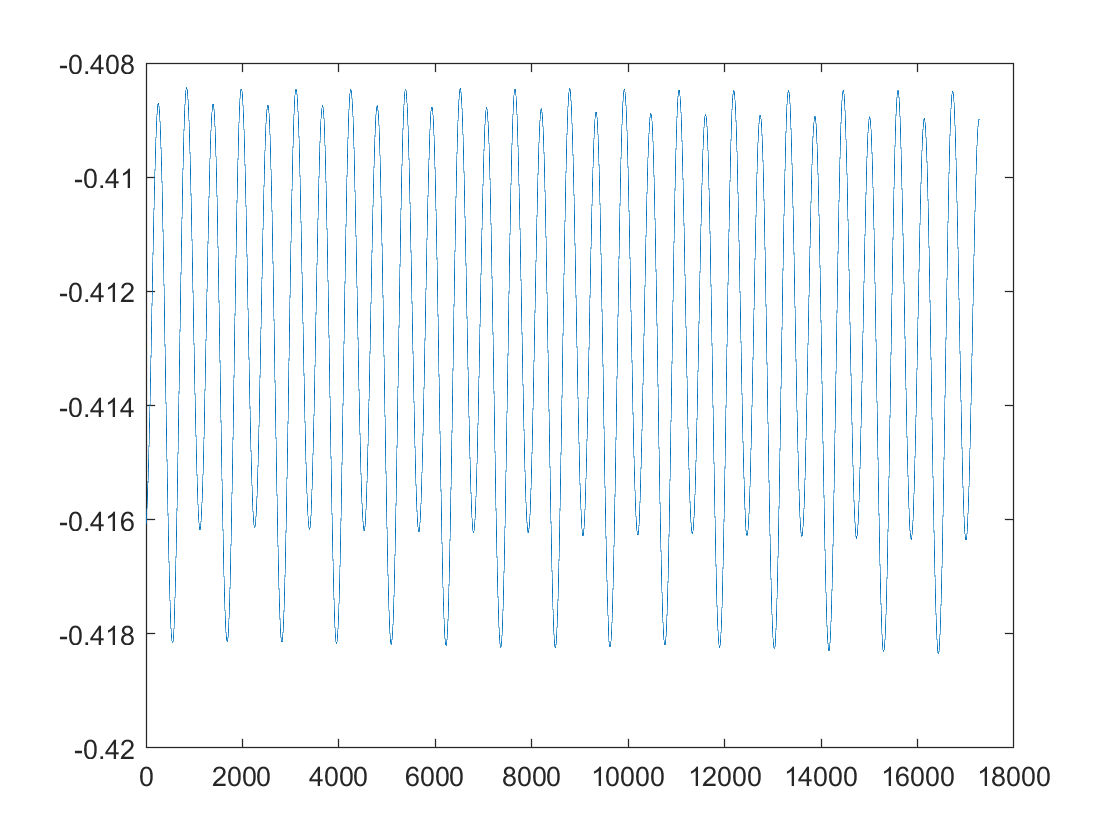

acc_grav = importdata("..//..//temp//acc_grav_calibra1.txt");
%vel_grac = cumtrapz(acc_grav, 1);
acc_grav_rela = [acc_grav(:, 1) - acc_grav(:, 4), acc_grav(:, 2) - acc_grav(:, 5), acc_grav(:, 3) - acc_grav(:, 6)];
%vel_grav_rela = [vel_grav(:, 1) - vel_grav(:, 4), vel_grav(:, 2) - vel_grav(:, 5), vel_grav(:, 3) - vel_grav(:, 6)];
gnv_a = importdata("GNV1B_2020-09-17_C_04.txt");
gnv_b = importdata("GNV1B_2020-09-17_D_04.txt");
gni_a = importdata("GNI1B_2020-09-17_C_04.txt");
gni_b = importdata("GNI1B_2020-09-17_D_04.txt");
kbr_x = importdata("KBR1B_2020-09-17_Y_04.txt");
range_acc = kbr_x(:, 4);

pos_rela = gnv_a.data(:, 1: 3) - gnv_b.data(:, 1: 3);
pos_rela_i = gni_a.data(:, 1: 3) - gni_b.data(:, 1: 3);
los = pos_rela ./ sqrt(sum(pos_rela.^2, 2));
los_i = pos_rela_i ./ sqrt(sum(pos_rela_i.^2, 2));
vel_rela = gni_a.data(:, 7: 9) - gni_b.data(:, 7: 9);
los_vec = vel_rela ./ sqrt(sum(pos_rela.^2, 2)) - pos_rela_i .* dot(los_i, vel_rela, 2) ./ sum(pos_rela.^2, 2);

range_acc_grav = zeros(length(los), 1);
for i = 1: length(range_acc_grav)
    range_acc_grav(i) = dot(acc_grav_rela(i, :), los(i, :)) + dot(vel_rela(i, :), los_vec(i, :));
end
range_acc_grav = range_acc_grav(1: 5: length(range_acc_grav));
range_acc_res = range_acc - range_acc_grav;
figure; plot(range_acc_res)

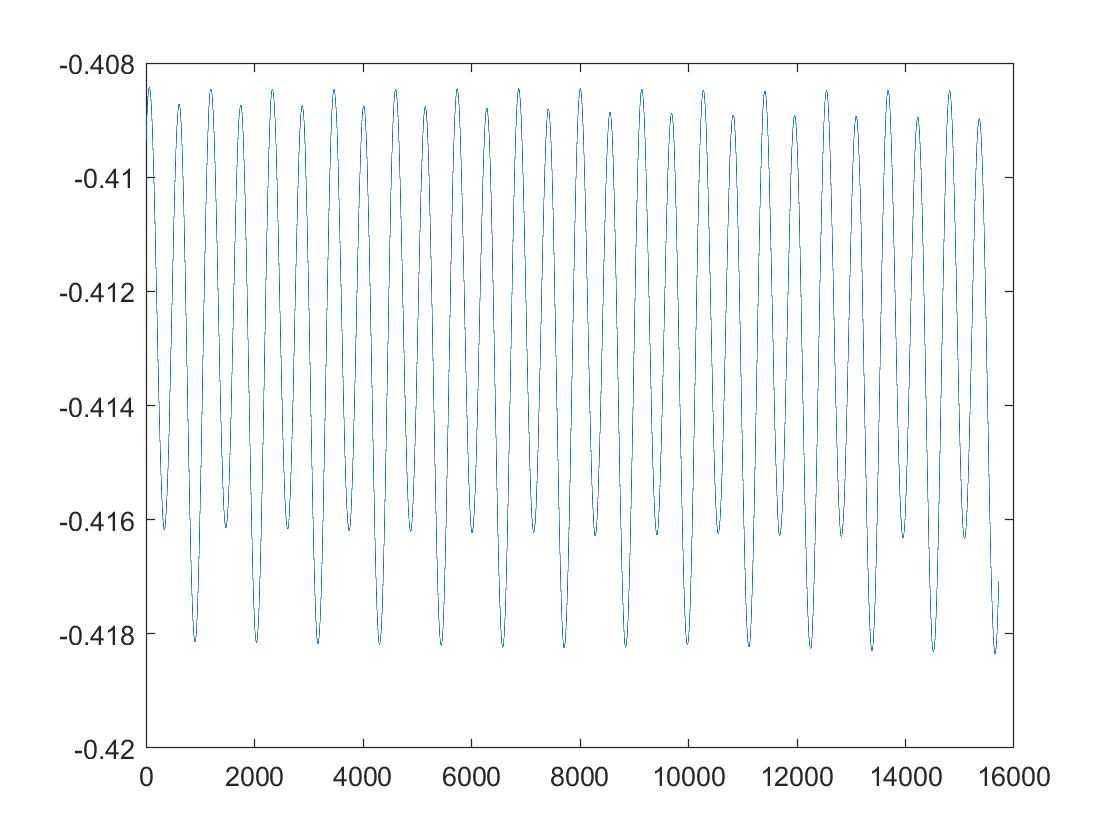

temp = filter_pdfree(Num1, range_acc_res);
figure; plot(temp)

spectral_component(filter_pdfree(Num, range_acc_res(10822: 11421)), 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 1。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 1。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 1。


ans =     25.5340488151456e-006
    13.3633018846419e-006


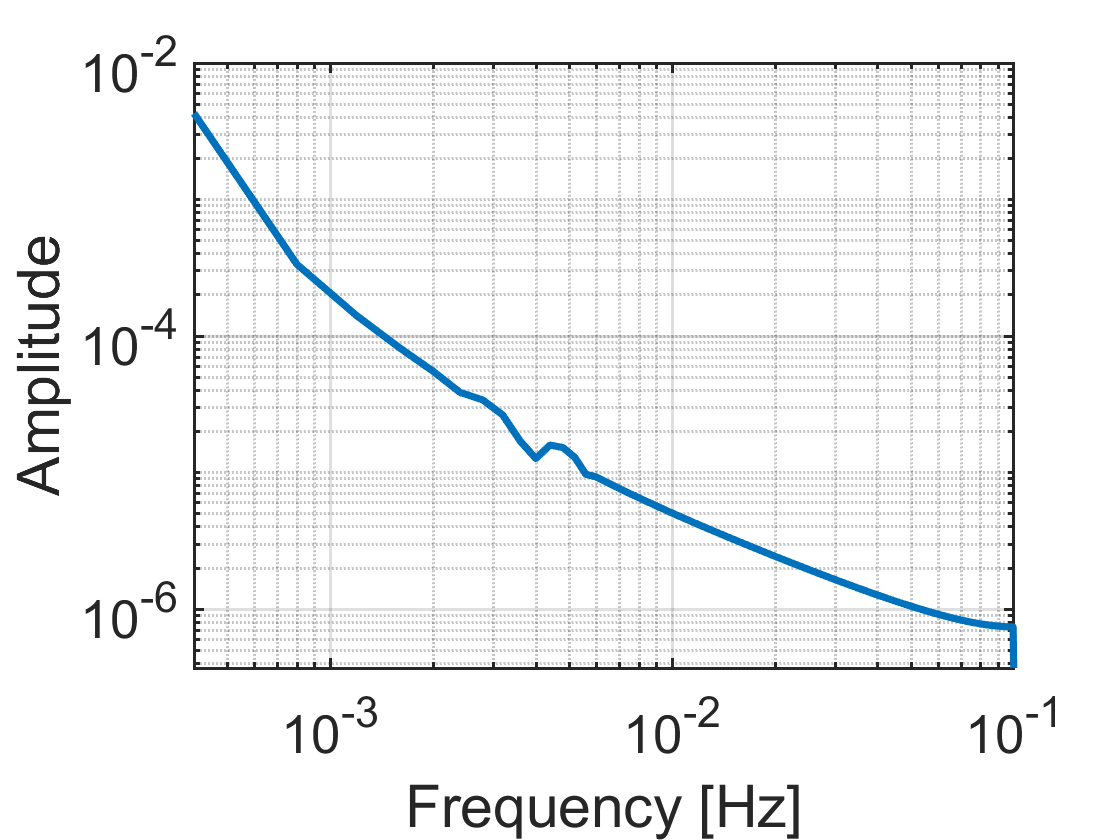

fft_plot(temp(2925: 2925+500), 0.2)

spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(10822: 11421, 4)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 1。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 1。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 1。


ans =     796.426672472511e-015
    3.53313028201503e-012


spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(10822: 11421, 5)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 1。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 1。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 1。


ans =     6.94694209033134e-009
    4.97579426286804e-009
